# Two Tank System: C MEX-File Modeling of Time-Continuous SISO System

This example shows how to perform IDNLGREY modeling based on C MEX model files. It uses a simple system where nonlinear state space modeling really pays off.

## A Two Tank System

The objective is to model the liquid level of the lower tank of a laboratory scale two tank system, schematically shown in Figure 1.

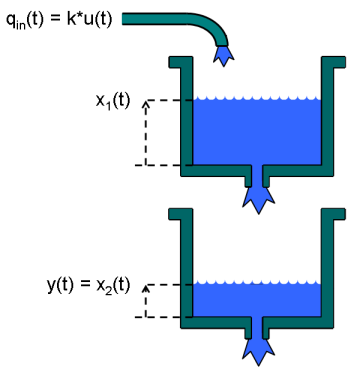

**Figure 1:** Schematic view of a two tank system.

## Input-Output Data

We start the modeling job by loading the available input-output data, which was simulated using the below IDNLGREY model structure, with noise added to the output. The twotankdata.mat file contains one data set with 3000 input-output samples, generated using a sampling rate (Ts) of 0.2 seconds. The input u(t) is the voltage [V] applied to a pump, which generates an inflow to the upper tank. A rather small hole at the bottom of this upper tank yields an outflow that goes into the lower tank, and the output y(t) of the two tank system is then the liquid level [m] of the lower tank. We create an IDDATA object z to hold the tank data. For bookkeeping and documentation purposes we also specify channel names and units. This step is optional.

load(fullfile(matlabroot, 'toolbox', 'ident', 'iddemos', 'data', 'twotankdata'));
z = iddata(y, u, 0.2, 'Name', 'Two tanks');
set(z, 'InputName', 'Pump voltage', 'InputUnit', 'V',             ...
    'OutputName', 'Lower tank water level', 'OutputUnit', 'm', ...
    'Tstart', 0, 'TimeUnit', 's');

The input-output data that will be used for estimation are shown in a plot window.

figure('Name', [z.Name ': input-output data']);
plot(z);

**Figure 2:** Input-output data from a two tank system.

## Modeling the Two Tank System

The next step is to specify a model structure describing the two tank system. To do this, let x1(t) and x2(t) denote the water level in the upper and the lower tank, respectively. For each tank, fundamental physics (mass balance) states that the change of water volume depends on the difference between in- and outflow as (i = 1, 2):

where Ai [m^2] is the cross-sectional area of tank i and Qini(t) and Qouti(t) [m^3/s] are the inflow to and the outflow from tank i at time t.

For the upper tank, the inflow is assumed to be proportional to the voltage applied to the pump, i.e., Qin1(t) = k*u(t). Since the outlet hole of the upper tank is small, Bernoulli's law can be applied, stating that the outflow is proportional to the square root of the water level, or more precisely that:

where a1 is the cross-sectional area of the outlet hole and g is the gravity constant. For the lower tank, the inflow equals the outflow from the upper tank, i.e., Qin2(t) = Qout1(t), and the outflow is given by Bernoulli's law:

where a2 is the cross-sectional area of the outlet hole.

Put altogether these facts lead to the following state-space structure:

## Two Tank C MEX Model File

These equations are next put into a C MEX-file with 6 parameters (or constants), A1, k, a1, g, A2 and a2. The C MEX-file is normally a bit more involved than the corresponding file written using MATLAB language, but C MEX modeling generally gives a distinct advantage in terms of execution speed, especially for more complex models. A template C MEX-file is provided (see below) to help the user to structure the code. For most applications, it suffices to define the number of outputs and to enter the code lines that describe dx and y into this template. An IDNLGREY C MEX-file should always be structured to return two outputs:

and it should take 3+Npo(+1) input arguments specified as follows:

In our two tank system there are 6 scalar parameters and hence the number of input arguments to the C MEX modeling file should be 3+Npo = 3+6 = 9. The trailing 10:th argument can here be omitted as no optional FileArgument is employed in this application.

Writing a C MEX modeling file is normally done in four steps:

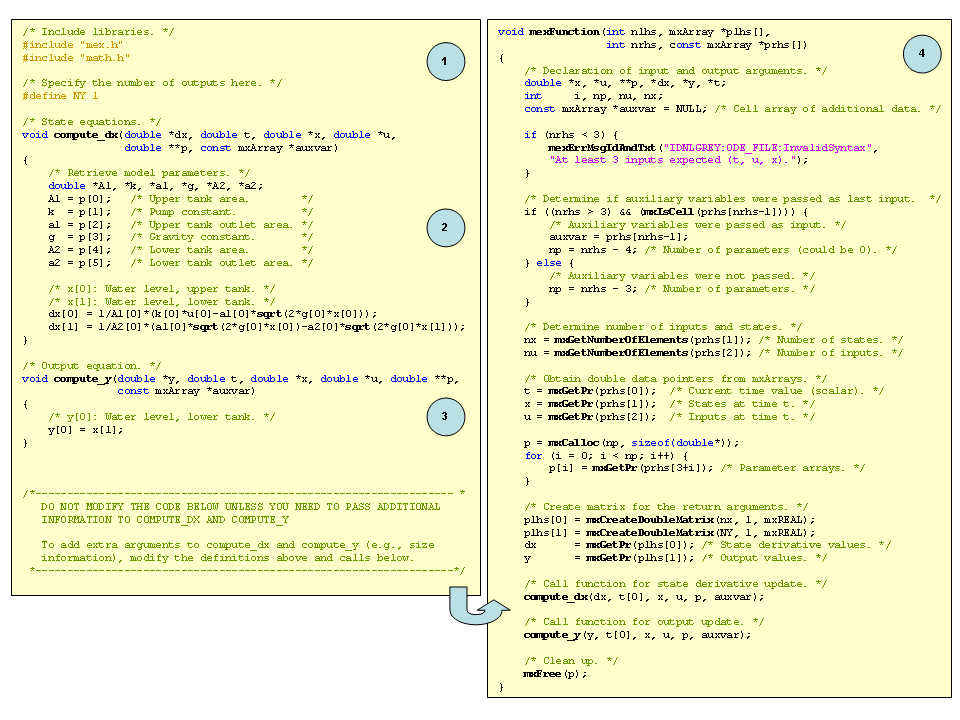

**Figure 3:** C MEX source code for the two tank system.

1. Two C-libraries mex.h and math.h are normally included to provide access to a number of MEX-related as well as mathematical functions. The number of outputs is also declared per modeling file using a standard C-define:

2-3. Next in the file we find the functions for updating the states, compute_dx, and the output, compute_y. Both these functions hold argument lists, with the output to be computed (dx or y) at position 1, after which follows all variables and parameters required to compute the right-hand side(s) of the state and the output equations, respectively.

The first step in these functions is to unpack the model parameters that will be used in the subsequent equations. Any valid variable name (except for those used in the input argument list) can be used to provide physically meaningful names of the individual parameters.

As is the case in C, the first element of an array is stored at position 0. Hence, dx[0] in C corresponds to dx(1) in MATLAB® (or just dx in case it is a scalar), the input u[0] corresponds to u (or u(1)), the parameter A1[0] corresponds to A1, and so on.

The two tank model file involves square root computations. This is enabled through the inclusion of the mathematical C library math.h. The math library realizes the most common trigonometric functions (sin, cos, tan, asin, acos, atan, etc.), exponential (exp) and logarithms (log, log10), square root (sqrt) and power of functions (pow), and absolute value computations (fabs). The math.h library must be included whenever any math.h function is used; otherwise it can be omitted. See "Tutorials on Nonlinear Grey Box Model Identification: Creating IDNLGREY Model Files" for further details about the C math library.

4. The main interface function should almost always have the same content and for most applications no modification whatsoever is needed. In principle, the only part that might be considered for changes is where the calls to compute_dx and compute_y are made. For static systems, one can leave out the call to compute_dx. In other situations, it might be desired to only pass the variables and parameters referred in the state and output equations. For example, in the output equation of the two tank system, where only one state is used, one could very well shorten the input argument list to:

and call compute_y as:

The input argument lists of compute_dx and compute_y might also be extended to include further variables inferred in the interface function, like the number of states and the number of parameters.

Once the model source file has been completed it must be compiled, which can be done from the MATLAB command prompt using the mex command; see "help mex". (This step is omitted here.)

When developing model specific C MEX-files it is often useful to start the work by copying the IDNLGREY C MEX template file. This template contains skeleton source code as well as detailed instructions on how to customize the code for a particular application. The location of the template file is displayed by typing the following at the MATLAB command prompt.

Also see "Creating IDNLGREY Model Files" example for more details on IDNLGREY C MEX model files.

## Creating a Two Tank IDNLGREY Model Object

The next step is to create an IDNLGREY object describing the two tank system. For convenience we also set some bookkeeping information about the inputs and outputs (name and units).

FileName      = 'twotanks_c';          % File describing the model structure.
Order         = [1 1 2];               % Model orders [ny nu nx].
Parameters    = {0.5; 0.0035; 0.019; ...
    9.81; 0.25; 0.016};   % Initial parameters.
InitialStates = [0; 0.1];              % Initial value of initial states.
Ts            = 0;                     % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts, ...
    'Name', 'Two tanks');
set(nlgr, 'InputName', 'Pump voltage', 'InputUnit', 'V',             ...
    'OutputName', 'Lower tank water level', 'OutputUnit', 'm', ...                          ...
    'TimeUnit', 's');

We continue to add information about the names and the units of the states and the model parameters via the commands SETINIT and SETPAR. Furthermore, both states x1(t) and x2(t) are tank levels that cannot be negative, and thus we also specify that x1(0) and x2(0) >= 0 via the 'Minimum' property. In fact, we also know that all model parameters ought to be strictly positive. We therefore set the 'Minimum' property of all parameters to some small positive value (eps(0)). These settings imply that constraint estimation will be carried out in the upcoming estimation step (i.e., the estimated model will be a model such that all entered constraints are honored).

nlgr = setinit(nlgr, 'Name', {'Upper tank water level' 'Lower tank water level'});
nlgr = setinit(nlgr, 'Unit', {'m' 'm'});
nlgr = setinit(nlgr, 'Minimum', {0 0});   % Positive levels!
nlgr = setpar(nlgr, 'Name', {'Upper tank area'        ...
    'Pump constant'          ...
    'Upper tank outlet area' ...
    'Gravity constant'       ...
    'Lower tank area'        ...
    'Lower tank outlet area'});
nlgr = setpar(nlgr, 'Unit', {'m^2' 'm^3/(s*V)' 'm^2'  'm/(s^2)' 'm^2' 'm^2'});
nlgr = setpar(nlgr, 'Minimum', num2cell(eps(0)*ones(6,1)));   % All parameters > 0!

The cross-sectional areas (A1 and A2) of the two tanks can rather accurately be determined. We therefore treat these and g as constants and verify that the 'Fixed' field is properly set for all 6 parameters through the command GETPAR. All in all, this means that 3 of the model parameters will be estimated.

nlgr.Parameters(1).Fixed = true;
nlgr.Parameters(4).Fixed = true;
nlgr.Parameters(5).Fixed = true;
getpar(nlgr, 'Fixed')

## Performance of the Initial Two Tank Model

Before estimating the free parameters k, a1 and a2 we simulate the system using the initial parameter values. We use the default differential equation solver (a Runge-Kutta 45 solver with adaptive step length adjustment) and set the absolute and relative error tolerances to rather small values (1e-6 and 1e-5, respectively). Notice that the COMPARE command, when called with two input arguments, as default will estimate all initial state(s) regardless of whether any initial state has been defined to be 'Fixed'. In order to only estimate the free initial state(s), call COMPARE with a third and a fourth input argument as follows: compare(z, nlgr, 'init', 'm'); as both initial states of the tank model by default are 'Fixed', no initial state estimation will be performed by this command.

nlgr.SimulationOptions.AbsTol = 1e-6;
nlgr.SimulationOptions.RelTol = 1e-5;

compare(z, nlgr);

**Figure 4:** Comparison between true output and the simulated output of the initial two tank model.

The simulated and true outputs are shown in a plot window, and as can be seen the fit is not so impressive.

## Parameter Estimation

In order to improve the fit, the 3 free parameters are next estimated using NLGREYEST. (Since, by default, the 'Fixed' fields of all initial states are false, no estimation of the initial states will be done in this call to the estimator.)

nlgr = nlgreyest(z, nlgr, nlgreyestOptions('Display', 'on'));

## Performance of the Estimated Two Tank Model

To investigate the performance of the estimated model, a simulation of it is performed (the initial states are here reestimated).

compare(z, nlgr);

**Figure 5:** Comparison between true output and the simulated output of the estimated two tank model.

The agreement between the true and the simulated outputs is quite good. A remaining question is, however, if the two tank system can be accurately described using a simpler and linear model structure. To answer this, let us try to fit the data to some standard linear model structures, and then use COMPARE to see how well these models capture the dynamics of the tanks.

nk = delayest(z);
arx22 = arx(z, [2 2 nk]);   % Second order linear ARX model.
arx33 = arx(z, [3 3 nk]);   % Third order linear ARX model.
arx44 = arx(z, [4 4 nk]);   % Fourth order linear ARX model.
oe22  = oe(z,  [2 2 nk]);   % Second order linear OE model.
oe33  = oe(z,  [3 3 nk]);   % Third order linear OE model.
oe44  = oe(z,  [4 4 nk]);   % Fourth order linear OE model.
sslin = ssest(z);           % State-space model (order determined automatically)
compare(z, nlgr, 'b', arx22, 'm-', arx33, 'm:', arx44, 'm--', ...
    oe22, 'g-', oe33, 'g:', oe44, 'g--', sslin, 'r-');

**Figure 6:** Comparison between true output and the simulated outputs of a number of estimated two tank models.

The comparison plot clearly reveals that the linear models cannot pick up all dynamics of the two tank system. The estimated nonlinear IDNLGREY model on the other hand shows an excellent fit to the true output. In addition, the IDNLGREY model parameters are also well in line with those used to generate the true output. In the following display computations, we are using the command GETPVEC, which returns a parameter vector created from the structure array holding the model parameters of an IDNLGREY object.

disp('   True      Estimated parameter vector');
ptrue = [0.5; 0.005; 0.02; 9.81; 0.25; 0.015];
fprintf('   %1.4f    %1.4f\n', [ptrue'; getpvec(nlgr)']);

The prediction errors obtained using PE are small and look very much like random noise.

figure;
pe(z, nlgr);

**Figure 7:** Prediction errors obtained for the estimated IDNLGREY two tank model.

Let us also investigate what happens if the input voltage is increased from 5 to 6, 7, 8, 9 and 10 V in a step-wise manner. We do this by calling STEP with different specified step amplitudes starting from a fixed offset of 5 Volts. The step response configuration is facilitated by a dedicated option-set created by `stepDataOptions`:

figure('Name', [nlgr.Name ': step responses']);
t = (-20:0.1:80)';
Opt = stepDataOptions('InputOffset',5,'StepAmplitude',6);
step(nlgr, t, 'b', Opt);
hold on

Opt.StepAmplitude = 7;  step(nlgr, t, 'g', Opt);
Opt.StepAmplitude = 8;  step(nlgr, t, 'r', Opt);
Opt.StepAmplitude = 9;  step(nlgr, t, 'm', Opt);
Opt.StepAmplitude = 10; step(nlgr, t, 'k', Opt);

grid on;
legend('5 -> 6 V', '5 -> 7 V', '5 -> 8 V', '5 -> 9 V', '5 -> 10 V', ...
    'Location', 'Best');

**Figure 8:** Step responses obtained for the estimated IDNLGREY two tank model.

By finally using the PRESENT command, we get summary information about the estimated model:

present(nlgr);

## Conclusions

In this example we have shown:

## Additional Information

For more information on identification of dynamic systems with System Identification Toolbox™ visit the [System Identification Toolbox](http://www.mathworks.com/products/sysid/) product information page.

*Copyright 2005-2017 The MathWorks, Inc.*